# Driver test program to check clothoid computation 

%=========================================================================%
%                                                                         %
%  Autors: Enrico Bertolazzi                                              %
%          Department of Industrial Engineering                           %
%          University of Trento                                           %
%          enrico.bertolazzi@unitn.it                                     %
%                                                                         %
%=========================================================================%

## Data XY for the clothoid

tol = 1e-10;

XY = 1.0e+02 * [...
  -4.839456676074770,  -0.687801210926846; ...
  -4.854012555484660,  -0.702211958309636; ...
  -4.863436554332729,  -0.718581445114687; ...
  -4.869128276407719,  -0.735790389403701; ...
  -4.875846374598332,  -0.791894321963191; ...
  %-4.879112116773613,  -0.797350812163204; ...
  -4.879112116773613,  -0.797350812163204; ...
  -4.891242016281467,  -0.801967842094600; ...
  -4.899266411340795,  -0.791194771928713; ...
];
X = XY(:,1); Y = XY(:,2);

## Close all windows

close all;

## Initialize G2 clothoid spline object

S  = ClothoidSplineG2();
%S.ipopt(true);       if you have ipopt and not Optimization toolbox
%S.ipopt_check(true);

## Compute various G2 clothoid spline with different target

SPL = cell(8,1);

SPL{1} = S.buildP1( X, Y, -pi, -pi ); %3.141592653589793, 7.647610983392527 );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         3.30494            8.97         0.01
     1           2       0.0109938           0.458        0.001        1.29884
     2           3     1.84907e-08          0.0008       0.0001      0.0246351
     3           4      2.0455e-18        3.64e-09        1e-05    2.49864e-05
     4           5     7.57087e-28        2.13e-13        1e-06    1.30514e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{3} = S.buildP3( X, Y, SPL{1}.thetaBegin(), SPL{1}.kappaBegin() );

SPL{1} = S.buildP1( X, Y, -pi/2, 0 ); %3.141592653589793, 7.647610983392527 );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         7.34319            8.97         0.01
     1           2        0.293412            2.53        0.001         2.3882
     2           3     3.72327e-05          0.0283       0.0001       0.125367
     3           4     7.27323e-13        3.85e-06        1e-05     0.00143369
     4           5     4.60338e-25        2.07e-12        1e-06    2.07016e-07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{2} = S.buildP2( X, Y );


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           1         5.91617            8.97         0.01
     1           2       0.0768213           0.698        0.001        1.38639
     2           3     3.82438e-06         0.00669       0.0001       0.100721
     3           4     6.17505e-16        9.88e-08        1e-05    0.000569549
     4           5     2.96418e-27        7.67e-14        1e-06    9.67624e-09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

SPL{4} = S.buildP4( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    4.240764e+00     8.523e-01     1.000e+00     0.000e+00     1.330e+01  
    1           3    2.631595e-01     1.306e+00     1.000e+00     3.230e+00     9.063e+00  
    2           7    4.641083e-01     6.353e-01     4.900e-01     3.446e-01     5.575e+00  
    3           9    7.880882e-01     1.300e-02     1.000e+00     1.864e-01     8.432e-01  
    4          11    7.273491e-01     7.284e-04     1.000e+00     1.581e-01     2.927e-01  
    5          13    7.221241e-01     4.230e-05     1.000e+00     6.373e-02     5.469e-02  
    6          15    7.220041e-01     2.090e-06     1.000e+00     1.065e-02     3.072e-04  
    7          17    7.220041e-01     3.044e-10     1.000e+00     1.240e-04     9.053e-07  
    8          19    7.220041e-01     1.332e-15     1.000e+00     7.875e-11     5.

SPL{5} = S.buildP5( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    3.433329e+00     8.523e-01     1.000e+00     0.000e+00     1.195e-01  
    1           3    3.415094e+00     3.116e-03     1.000e+00     2.136e-01     1.299e-01  
    2           5    3.413135e+00     1.108e-04     1.000e+00     4.716e-02     3.529e-02  
    3           7    3.410169e+00     1.926e-03     1.000e+00     1.638e-01     2.909e-03  
    4           9    3.410187e+00     1.495e-06     1.000e+00     4.245e-03     2.154e-03  
    5          11    3.410179e+00     8.722e-07     1.000e+00     7.060e-03     2.770e-04  
    6          13    3.410179e+00     2.408e-08     1.000e+00     8.484e-04     2.540e-05  
    7          15    3.410179e+00     1.926e-09     1.000e+00     1.442e-04     1.789e-06  
    8          17    3.410179e+00     3.446e-12     1.000e+00     6.327e-06     8.

SPL{6} = S.buildP6( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.484604e+01     8.523e-01     1.000e+00     0.000e+00     2.485e-01  
    1           3    1.485195e+01     2.601e-03     1.000e+00     2.039e-01     8.450e-02  
    2           5    1.485203e+01     1.669e-06     1.000e+00     6.810e-03     4.762e-03  
    3           7    1.485198e+01     1.278e-05     1.000e+00     2.079e-02     7.079e-04  
    4           9    1.485197e+01     1.605e-08     1.000e+00     8.906e-04     5.087e-04  
    5          11    1.485197e+01     3.334e-08     1.000e+00     1.826e-03     2.005e-05  
    6          13    1.485197e+01     4.024e-11     1.000e+00     4.970e-05     1.489e-06  
    7          15    1.485197e+01     3.826e-13     1.000e+00     3.829e-06     1.928e-09  



SPL{7} = S.buildP7( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    2.668399e+00     8.523e-01     1.000e+00     0.000e+00     1.921e+00  
    1           3    4.424500e+00     1.281e-01     1.000e+00     1.441e+00     3.649e+00  
    2           5    2.208712e+00     2.196e-01     1.000e+00     1.065e+00     1.086e+00  
    3           7    2.200740e+00     1.385e-03     1.000e+00     1.942e-01     3.822e-01  
    4           9    2.185125e+00     9.794e-05     1.000e+00     1.287e-01     1.931e-01  
    5          11    2.184271e+00     1.809e-05     1.000e+00     7.467e-02     1.117e-01  
    6          13    2.181989e+00     2.317e-05     1.000e+00     3.635e-02     1.330e-02  
    7          15    2.181969e+00     2.672e-07     1.000e+00     3.541e-03     1.343e-03  
    8          17    2.181969e+00     2.129e-09     1.000e+00     4.856e-04     1.

SPL{8} = S.buildP8( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.077396e+01     8.523e-01     1.000e+00     0.000e+00     5.371e+01  
    1           3    7.239206e+00     1.306e+00     1.000e+00     3.307e+00     3.843e+01  
    2           5    7.036979e+00     9.389e-02     1.000e+00     2.003e+00     1.425e+01  
    3           7    4.140350e+00     2.852e-01     1.000e+00     1.541e+00     7.837e+00  
    4           9    3.940383e+00     1.009e-02     1.000e+00     4.190e-01     1.023e+00  
    5          11    3.865993e+00     5.659e-05     1.000e+00     1.974e-01     2.299e-01  
    6          13    3.865062e+00     9.048e-06     1.000e+00     1.993e-02     4.238e-03  
    7          15    3.865062e+00     1.708e-09     1.000e+00     2.915e-04     2.135e-05  
    8          17    3.865062e+00     1.174e-14     1.000e+00     4.409e-10     4.

SPL{9} = S.buildP9( X, Y );

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.428862e+01     8.523e-01     1.000e+00     0.000e+00     5.902e+01  
    1           6    8.259686e+00     5.492e-01     3.430e-01     1.135e+00     2.747e+01  
    2           8    2.440917e+00     3.408e-02     1.000e+00     6.772e-01     3.765e+01  
    3          10    2.181502e+00     3.144e-03     1.000e+00     1.890e-01     6.783e+00  
    4          12    2.156287e+00     2.249e-04     1.000e+00     4.588e-02     1.334e-01  
    5          15    2.156333e+00     6.812e-05     7.000e-01     1.156e-02     5.800e-02  
    6          17    2.156165e+00     2.049e-06     1.000e+00     1.034e-02     4.074e-02  
    7          19    2.156139e+00     2.170e-07     1.000e+00     1.906e-03     6.407e-03  
    8          21    2.156139e+00     4.600e-09     1.000e+00     3.185e-04     2.

## Plot results

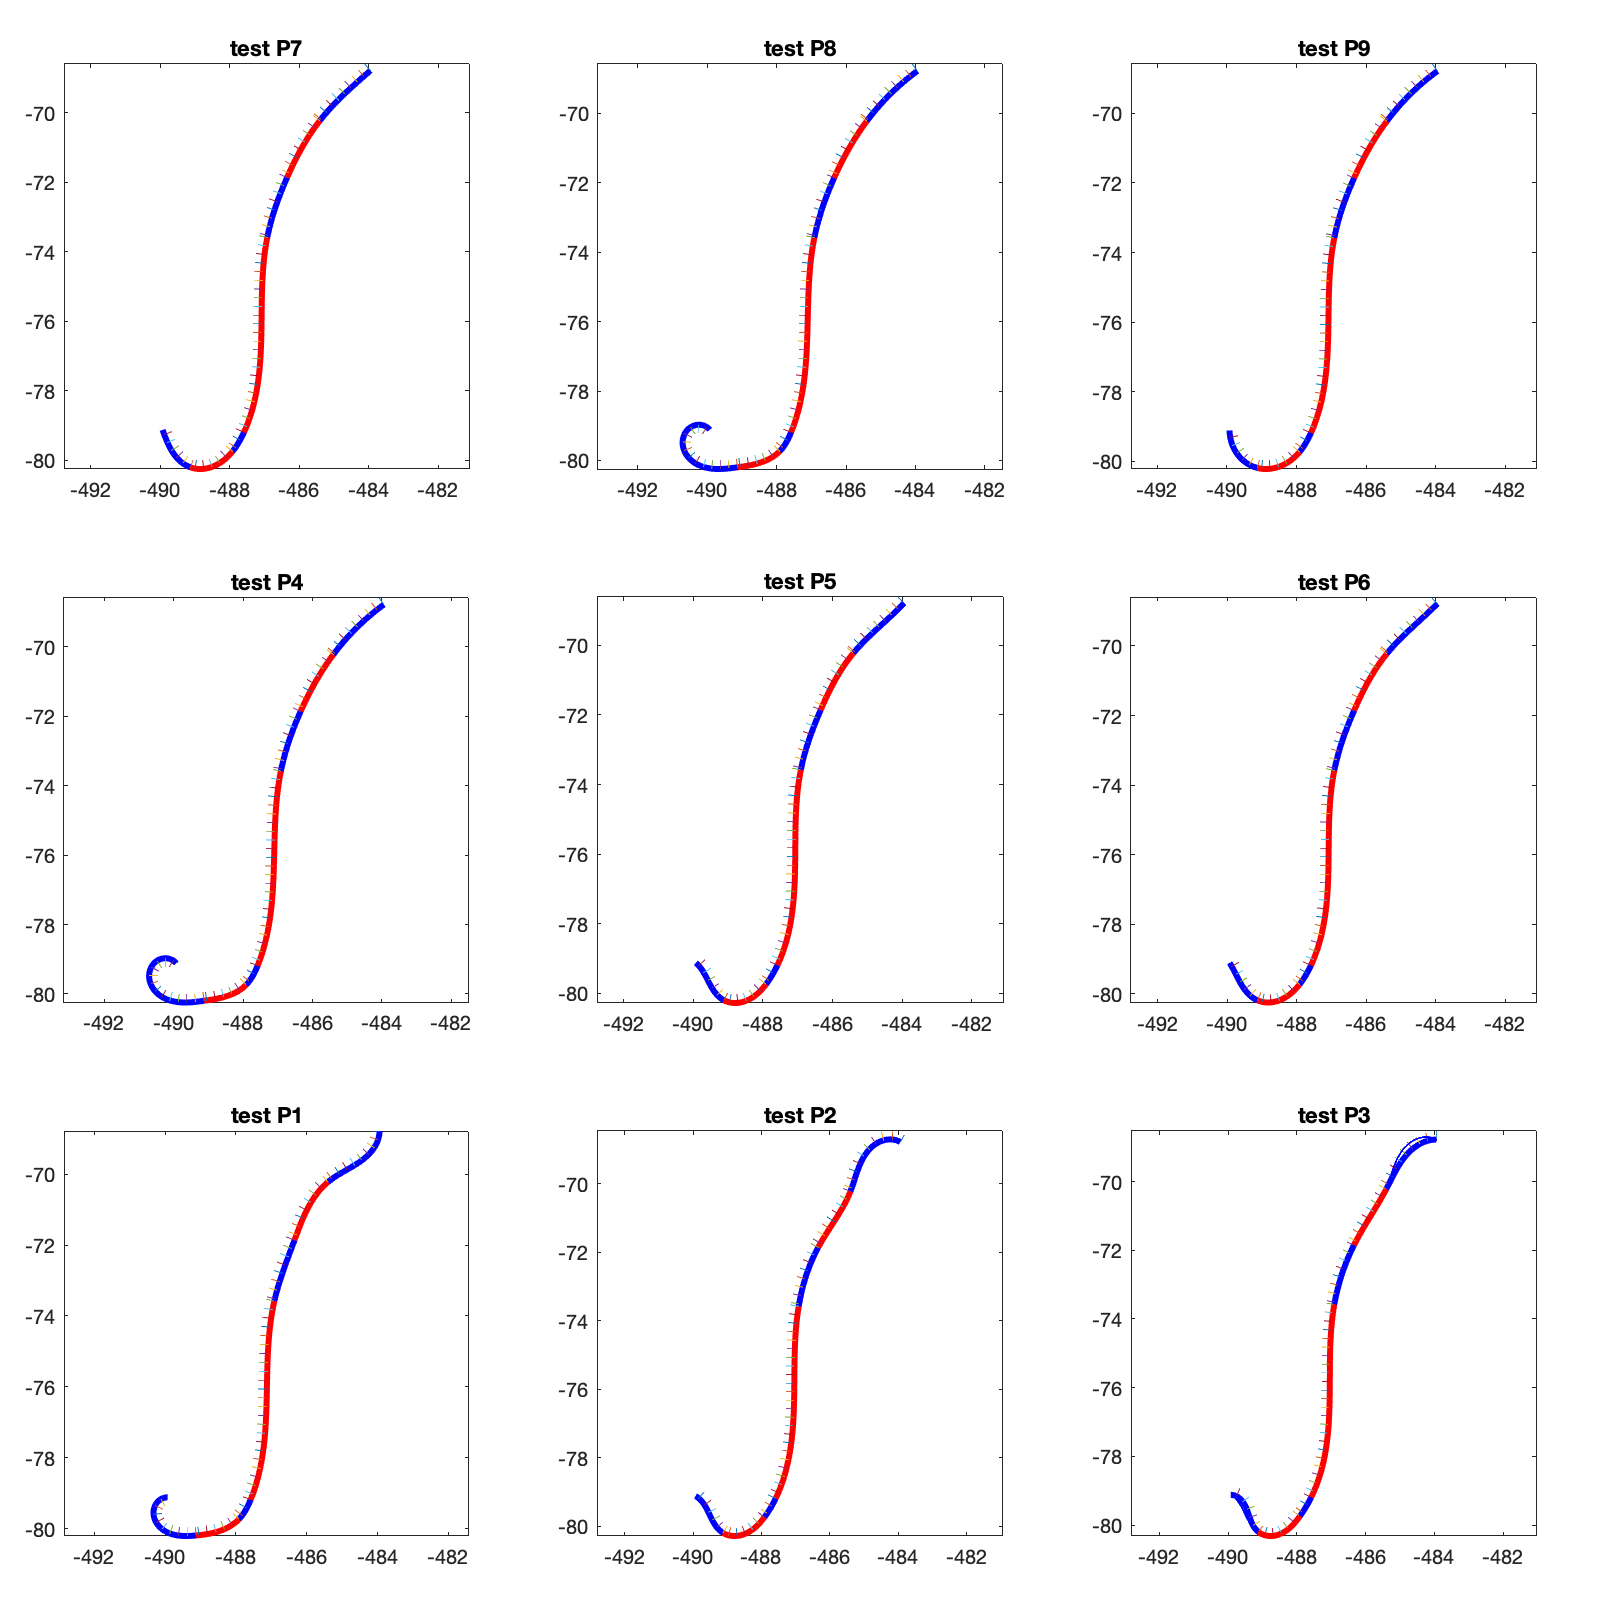

aa = 0.04;
bb = 1/3-2*aa;

figure('Position',[ 1 1 800 800]);

for k=1:9
  switch(k)
  case 1; subplot('Position',[aa     aa     bb bb]);
  case 2; subplot('Position',[aa+1/3 aa     bb bb]);
  case 3; subplot('Position',[aa+2/3 aa     bb bb]);
  case 4; subplot('Position',[aa     aa+1/3 bb bb]);
  case 5; subplot('Position',[aa+1/3 aa+1/3 bb bb]);
  case 6; subplot('Position',[aa+2/3 aa+1/3 bb bb]);
  case 7; subplot('Position',[aa     aa+2/3 bb bb]);
  case 8; subplot('Position',[aa+1/3 aa+2/3 bb bb]);
  case 9; subplot('Position',[aa+2/3 aa+2/3 bb bb]);
  end
  
  % subplot(3,3,k);
  SPL{k}.plot();
  SPL{k}.plotNormal(0.25,0.25);

  if k == 3
    hold on
    SPL{2}.plot(1000,{'Color','red','LineWidth',1},{'Color','blue','LineWidth',1});
  end

  title(sprintf('test P%d',k));

  axis equal;
end